# Analysis of the Simulation Data from Triple-Well Potential

clearvars;
addpath(genpath('../'))

## Generating simulation data

rng(1)
x_0 = [-1,0]';
par.T_max = 100;  
par.dt = 1e-2;
sigma = 0.8; % 1.2,1.5
[x_out, t_out] = generating_simulation_data (@triple_well_gradient_neg, sigma, x_0, par);

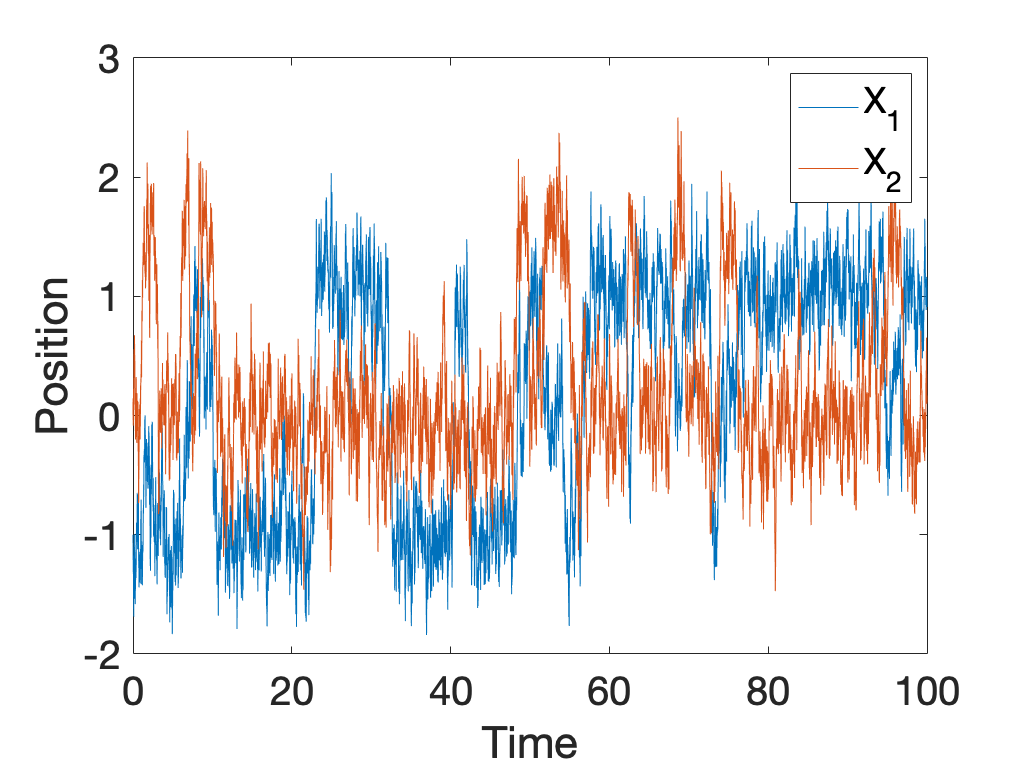

figure;
plot(t_out,x_out)
set(gca,'FontSize',20)
legend('X_{1}','X_{2}')
xlabel('Time')
ylabel('Position')

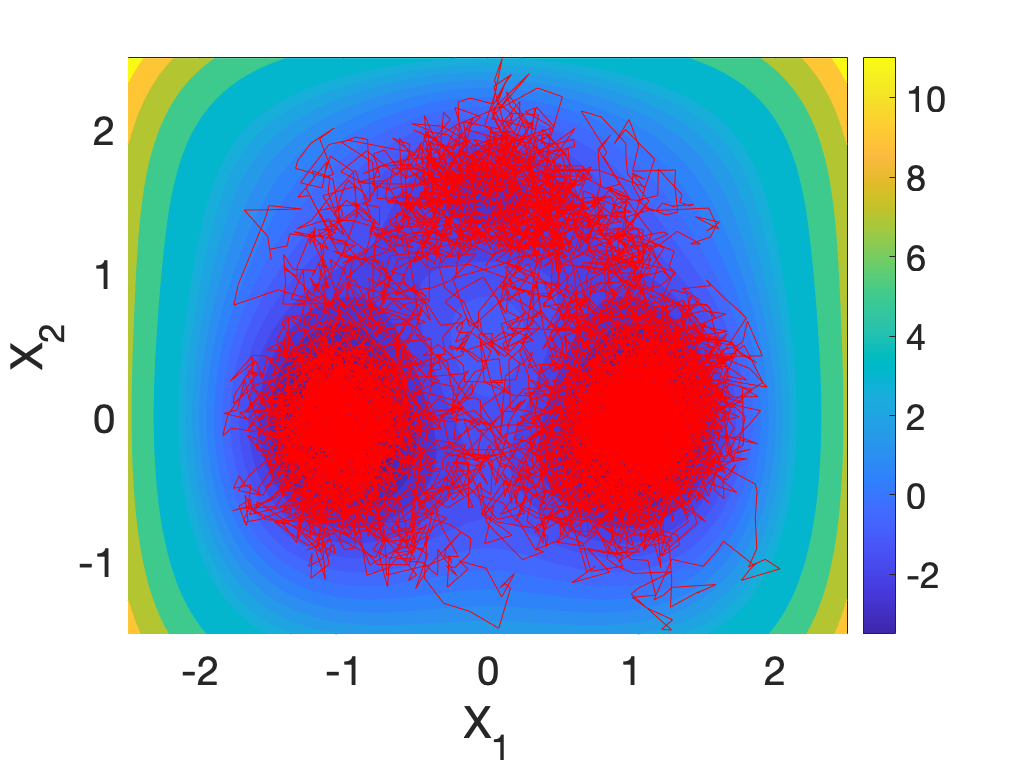

figure;
fc = fcontour(@triple_well_potential,[-2.5 2.5 -1.5 2.5],'Fill',"on" );
fc.LevelList = [-10:0.5:3,3:2:50];
colorbar
hold on
plot(x_out(1,:),x_out(2,:),"Color",'r','LineWidth',0.2)
xlabel('X_{1}')
ylabel('X_{2}')
set(gca,'FontSize',20)


data = x_out(:,1:5:end)';
%save 
%{
save('../Data/double_well.mat','x_out','t_out');
%}

## Load the Data and Estimate Number of Clusters by EPI

From EPI plot, we intend to seek for the index where peak occurs, which serves as the candidate for the choice of cluster numbers

out = EstClusterNum(data,[]);

Computed P-values 500 of 2001 datapoints...
Computed P-values 1000 of 2001 datapoints...
Computed P-values 1500 of 2001 datapoints...
Computed P-values 2000 of 2001 datapoints...
Mean value of sigma: 0.61654
Minimum value of sigma: 0.4928
Maximum value of sigma: 0.78183


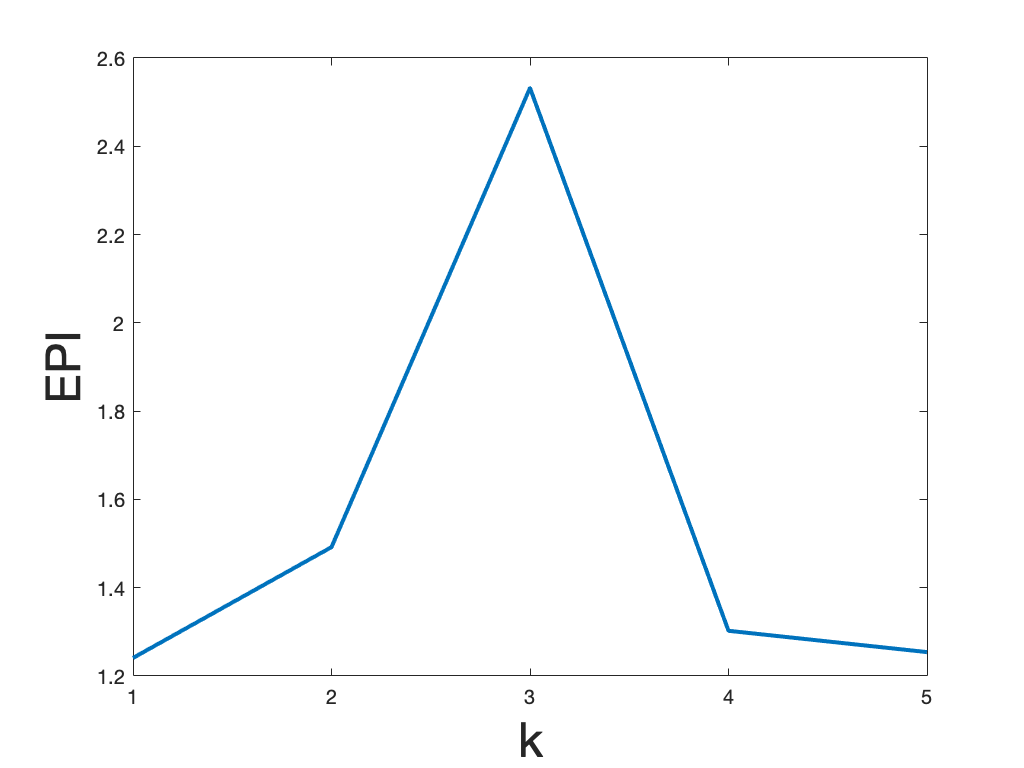

figure;
plot(out.ratio(1:5), 'linewidth',2.0)
xlabel('k', 'FontSize', 24);
ylabel('EPI', 'FontSize', 24);
xticks(0:30);

## Dynamical Analysis and Output

tic;
par.choice_distance = 'euclid';
par.K_cluster = 3; %selected based on EPI
par.trials = 2; % number of random trails in MuTrans, increase this to guaratee more robustness
par.initial = 'random';
% the main function of MuTrans
Output = DynamicalAnalysis (data, par);

Computed P-values 500 of 2001 datapoints...
Computed P-values 1000 of 2001 datapoints...
Computed P-values 1500 of 2001 datapoints...
Computed P-values 2000 of 2001 datapoints...
Mean value of sigma: 0.61654
Minimum value of sigma: 0.4928
Maximum value of sigma: 0.78183


J_new = 1.8788

J_new = 1.5264

J_new = 1.4310

J_new = 1.3600

J_new = 1.3389

J_new = 1.3370

J_new = 1.3361

J_new = 1.3356

J_new = 1.3350

J_new = 1.3344

J_new = 1.3344

J_new = 2.1691

J_new = 1.7141

J_new = 1.6497

J_new = 1.6321

J_new = 1.6197

J_new = 1.6060

J_new = 1.5878

J_new = 1.5664

J_new = 1.5358

J_new = 1.4971

J_new = 1.4413

J_new = 1.3711

J_new = 1.3485

J_new = 1.3424

J_new = 1.3387

J_new = 1.3374

J_new = 1.3361

J_new = 1.3352

J_new = 1.3350

J_new = 1.3348

J_new = 1.3344

J_new = 1.3344

E_best = 0.1221

                                                        First-order 
 Iteration  Func-count       f(x)        Step-size       optimality
     0           1          1.33688                      4.32e-05
     1          10          1.27642         104888       0.000344  
     2          12          1.27471       0.120435       0.000344  
     3          14           1.2667       0.261503       0.000296  
     4          16          1.26264        0.57029        0.00023  
     5          17          1.26189              1       0.000347  
     6          18          1.25815              1       0.000326  
     7          20          1.25667        0.40636       0.000178  
     8          21          1.25579              1       0.000242  
     9          22          1.25547              1       0.000313  
    10          23          1.25414              1       0.000161  
    11          25          1.25349       0.507507       0.000113  
    12          26          1.25284              

toc;

Elapsed time is 144.666496 seconds.



class_order = Output.class_order;
rho_class = Output.rho_class;
perm_class = Output.perm_class;
P_perm = Output.P_perm;
P_hat = Output.P_hat;
P_appr_perm = Output.P_appr_perm;
P_rho = Output.P_rho;
labs_perm = Output.labs_perm;
data_perm = Output.data_perm;
mu_hat = Output.mu_hat;
k = Output.k;
H = Output.H;

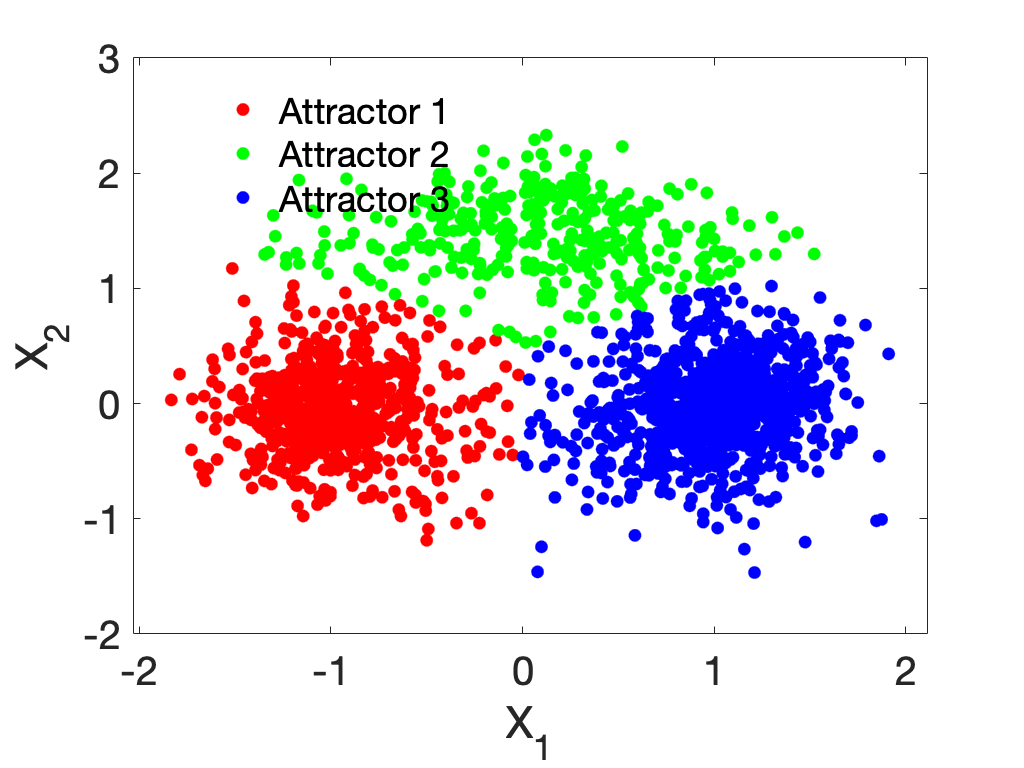

figure;
gscatter(data_perm(:,1),data_perm(:,2),class_order,[],[],20)
legend('Attractor 1','Attractor 2','Attractor 3')
xlabel('X_{1}')
ylabel('X_{2}')
set(gca,'FontSize',20)
legend boxoff   

Plot the Cell-Cell Scale rwTPM

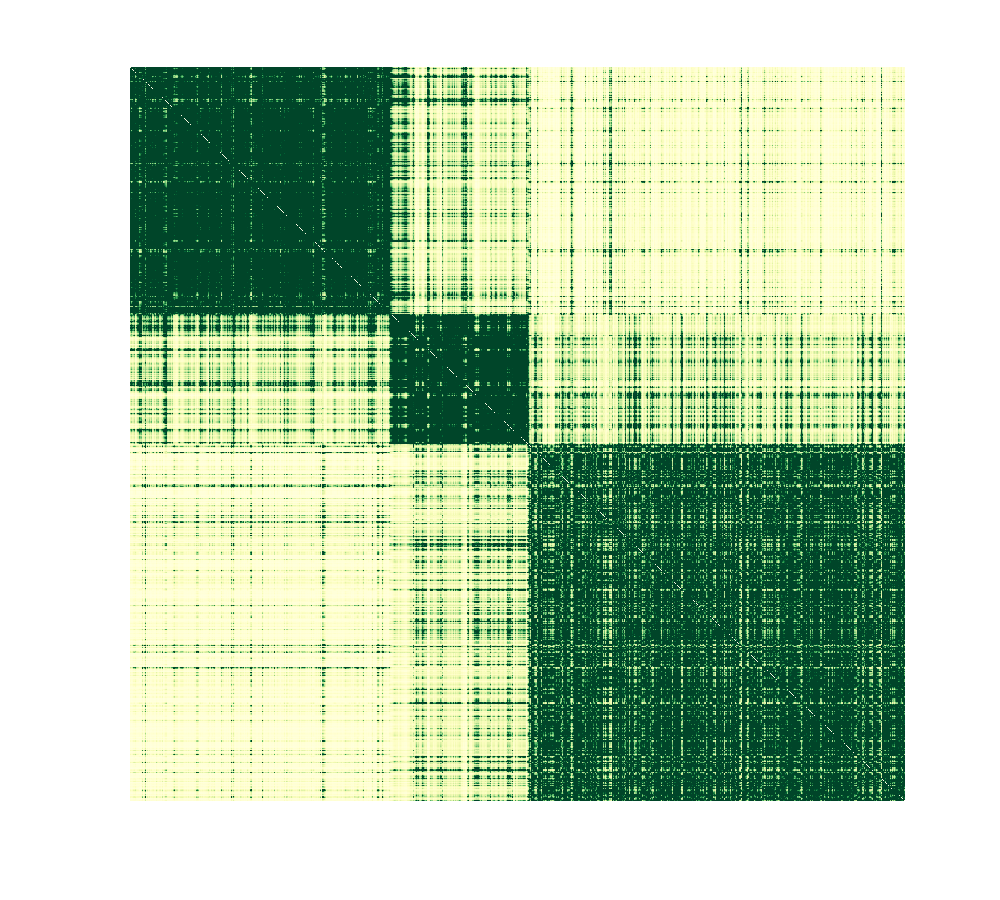

max_P = 0.2* max(max(P_rho));
c_lim = [0 max_P];
cmp = 'ylgn';

figure('rend','painters','pos',[10 10 500  450])
colormap(brewermap([],cmp))
imagesc(P_perm);
axis off
set(gca,'xtick',[],'ytick',[]);
caxis(c_lim)

%colorbar;

Plot the Cluster-Cluster Scale rwTPM

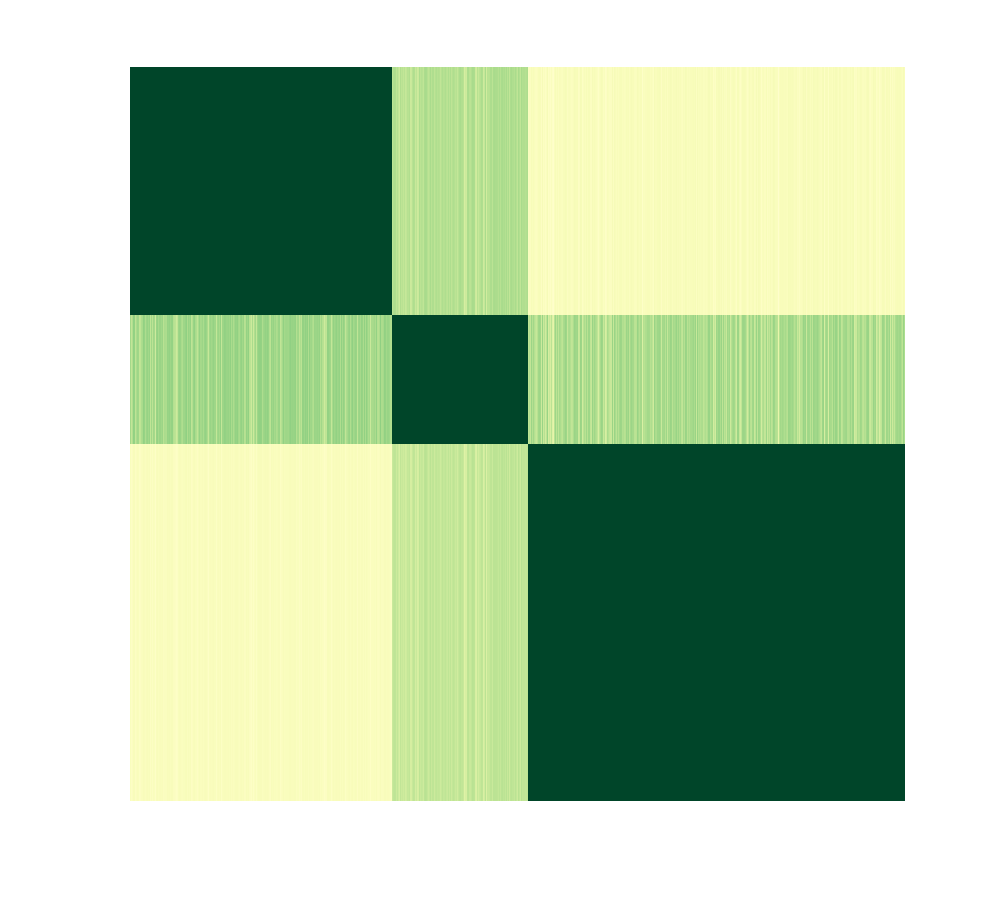

figure('rend','painters','pos',[10 10 500  450])
colormap(brewermap([],cmp))
imagesc(P_appr_perm);
axis off
set(gca,'xtick',[],'ytick',[]);
caxis(c_lim)

%colorbar;


Plot the Cell-Cluster Scale rwTPM

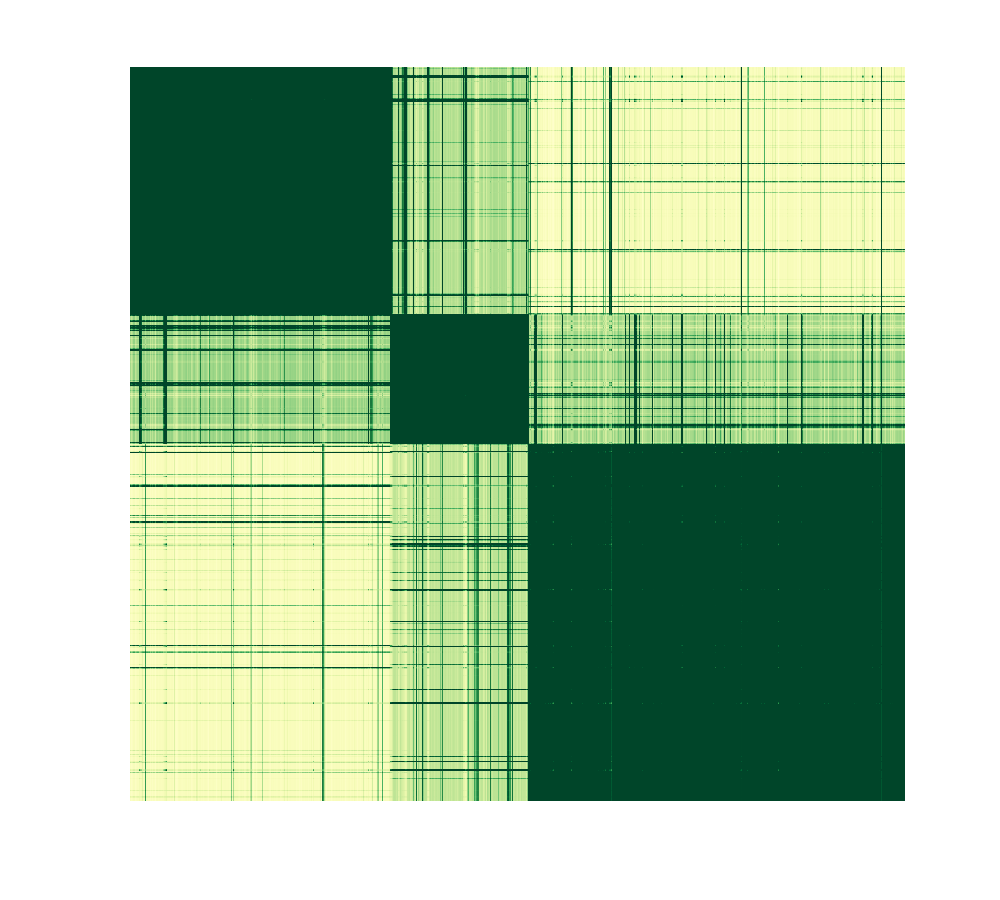


figure('rend','painters','pos',[10 10 500  450])
colormap(brewermap([],cmp))
imagesc(P_rho);
axis off
set(gca,'xtick',[],'ytick',[]);
caxis(c_lim)
%colorbar;
box off

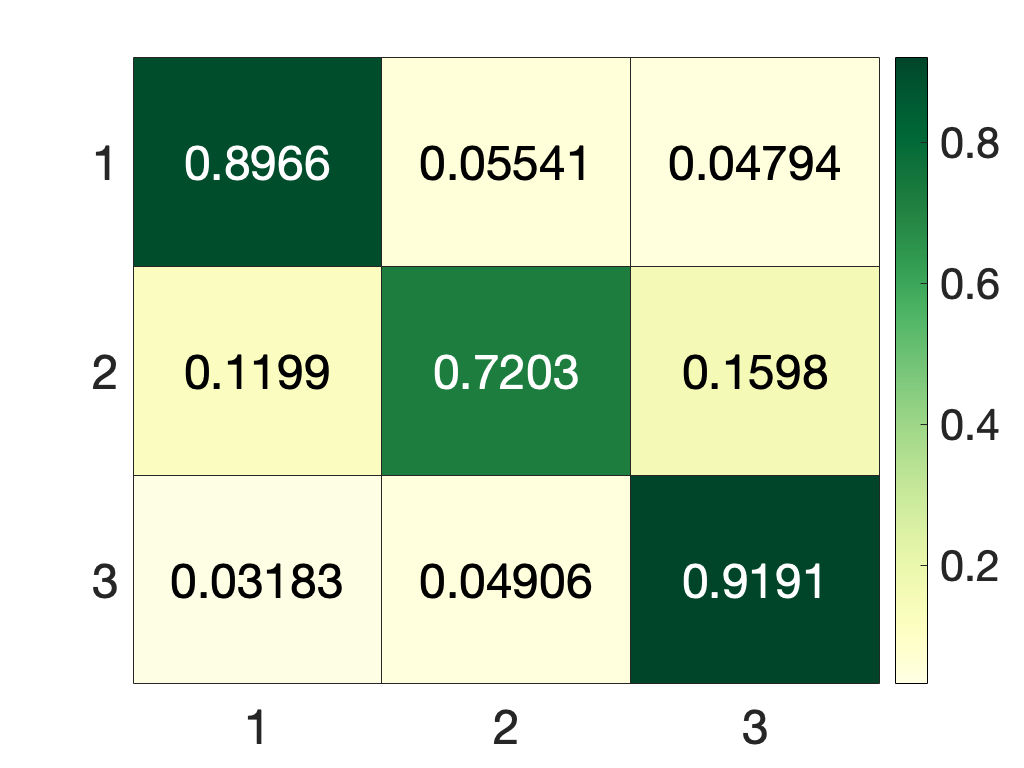

figure
heatmap(P_hat,'Colormap',colormap(brewermap([],cmp)),'FontSize',24)

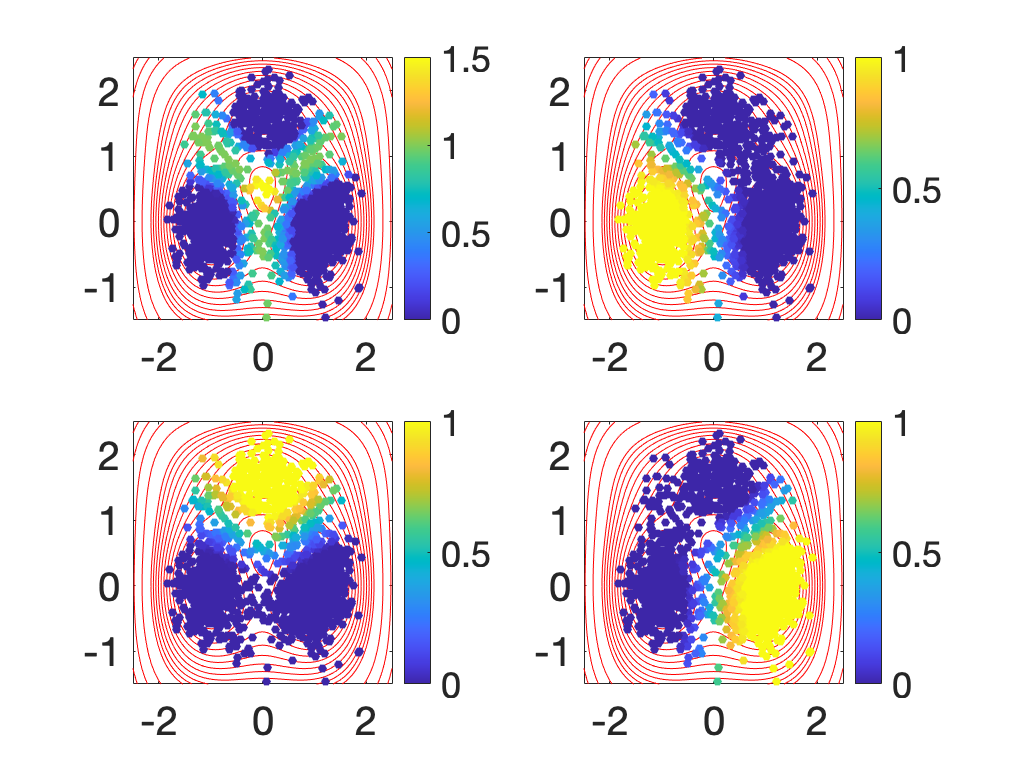

figure
subplot(2,2,1)
fc = fcontour(@triple_well_potential,[-2.5 2.5 -1.5 2.5],'-r');
fc.LevelList = [-5:0.5:3,3:2:15];
hold on
scatter(data_perm(:,1),data_perm(:,2),20,H,'filled')
colorbar 
caxis([0 1.5])
set(gca,'FontSize',20)

subplot(2,2,2)
fc = fcontour(@triple_well_potential,[-2.5 2.5 -1.5 2.5],'-r');
fc.LevelList = [-5:0.5:3,3:2:15];
hold on
scatter(data_perm(:,1),data_perm(:,2),20,rho_class(:,1),'filled') 
colorbar 
caxis([0 1])
set(gca,'FontSize',20)

subplot(2,2,3)
fc = fcontour(@triple_well_potential,[-2.5 2.5 -1.5 2.5],'-r');
fc.LevelList = [-5:0.5:3,3:2:15];
hold on
scatter(data_perm(:,1),data_perm(:,2),20,rho_class(:,2),'filled') 
colorbar 
caxis([0 1])
set(gca,'FontSize',20)

subplot(2,2,4)
fc = fcontour(@triple_well_potential,[-2.5 2.5 -1.5 2.5],'-r');
fc.LevelList = [-5:0.5:3,3:2:15];
hold on
scatter(data_perm(:,1),data_perm(:,2),20,rho_class(:,3),'filled') 
colorbar 
caxis([0 1])
set(gca,'FontSize',20)

function v = triple_well_potential(x,y)
    v = 3*exp(-x.^2-(y-1/3).^2)-3*exp(-x.^2-(y-5/3).^2)-5*exp(-(x-1).^2-y.^2)-5*exp(-(x+1).^2-y.^2)+0.2*x.^4+0.2*(y-1/3).^4;
end

function dv = triple_well_gradient_neg(x)
    dv = zeros(2,1);
    dv(1) = -6*x(1)*exp(-x(1)^2-(x(2)-1/3)^2)+6*x(1)*exp(-x(1)^2-(x(2)-5/3)^2)+10*(x(1)-1)*exp(-(x(1)-1).^2-x(2)^2)+10*(x(1)+1)*exp(-(x(1)+1).^2-x(2)^2)+0.8*x(1)^3;
    dv(2) = -6*(x(2)-1/3)*exp(-x(1)^2-(x(2)-1/3)^2)+6*(x(2)-5/3)*exp(-x(1)^2-(x(2)-5/3)^2)+10*x(2)*exp(-(x(1)-1).^2-x(2)^2)+10*x(2)*exp(-(x(1)+1).^2-x(2)^2)+0.8*(x(2)-1/3)^3;
    dv(1) = -dv(1);
    dv(2) = -dv(2);
end